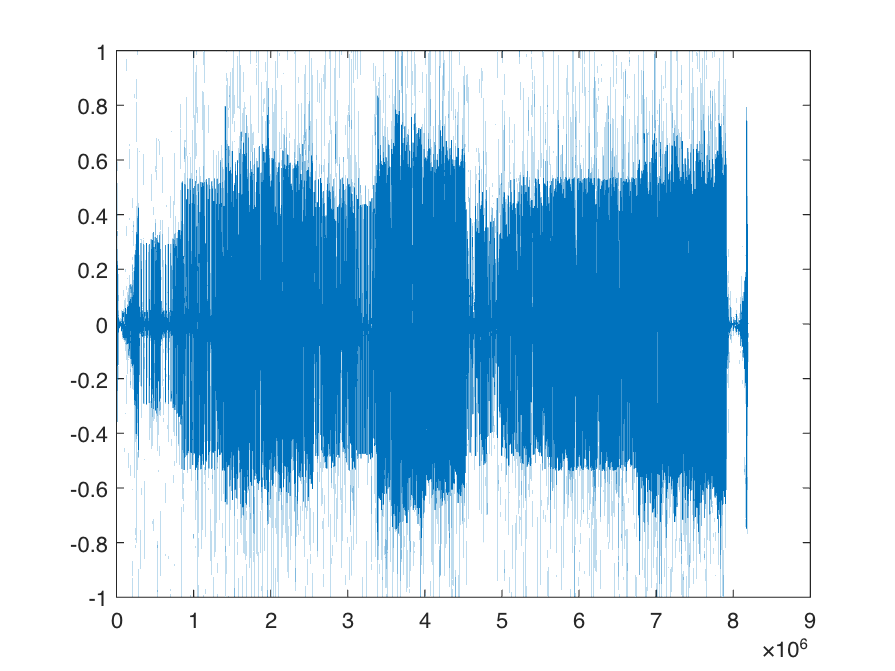

clear
audio = "heyhey.wav";
[Y, fs] = audioread(audio{1});
plot(Y)

raw_audio = Y(:,:);
step = 100;


Ymax = max(Y)

Ymax = 0.8347

Ymin = min(Y)

Ymin = -0.8619

delta = 0.02

delta = 0.0200

stepsize = (Ymax-Ymin) / step

stepsize = 0.0170

blocksize = 256;

raw_audio_blocks = reshape(raw_audio, blocksize,[] );

C = num2cell(raw_audio_blocks, 1); 


columnSums = cellfun(@dct, C,'UniformOutput',false);


y_transformed = dct(raw_audio);
%y_transformed = y_transformed(1:6000000,1);

max(y_transformed)

ans = 40.4186

min(y_transformed)

ans = -42.7049





y_quantize = cellfun(@(row) quantize(row, delta), columnSums, 'UniformOutput',false);

c = cellfun(@(row) uniqueIndex(row), y_quantize, 'UniformOutput',false);

c = reshape(cell2mat(c), [], 1)

c =      9
    25
     6
    26
     6
    28
     2
    30
    29
     1


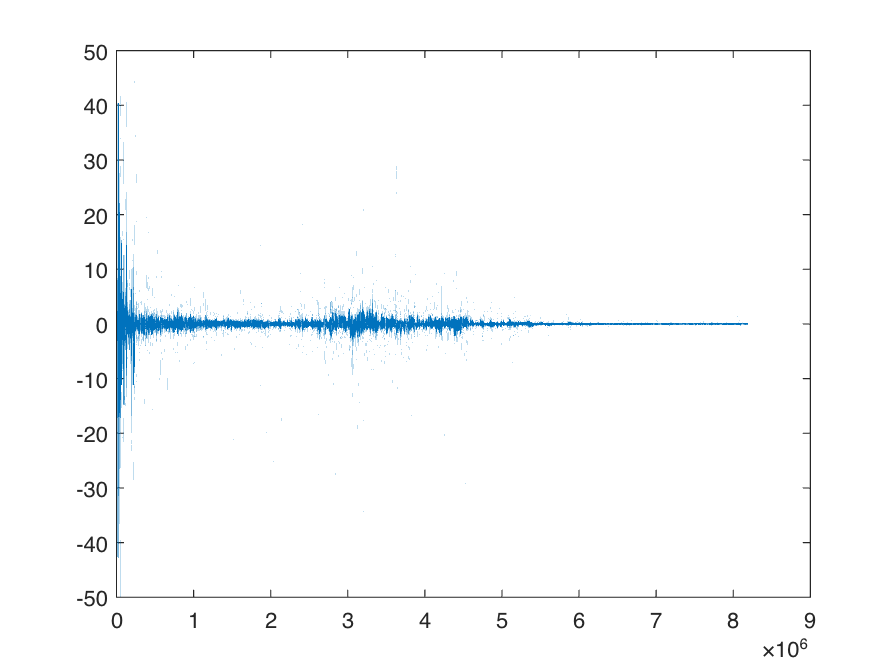

%[~,~,c] = unique(y_quantize)

num = accumarray(c,1);

p = num/sum(num);

plot(y_transformed)

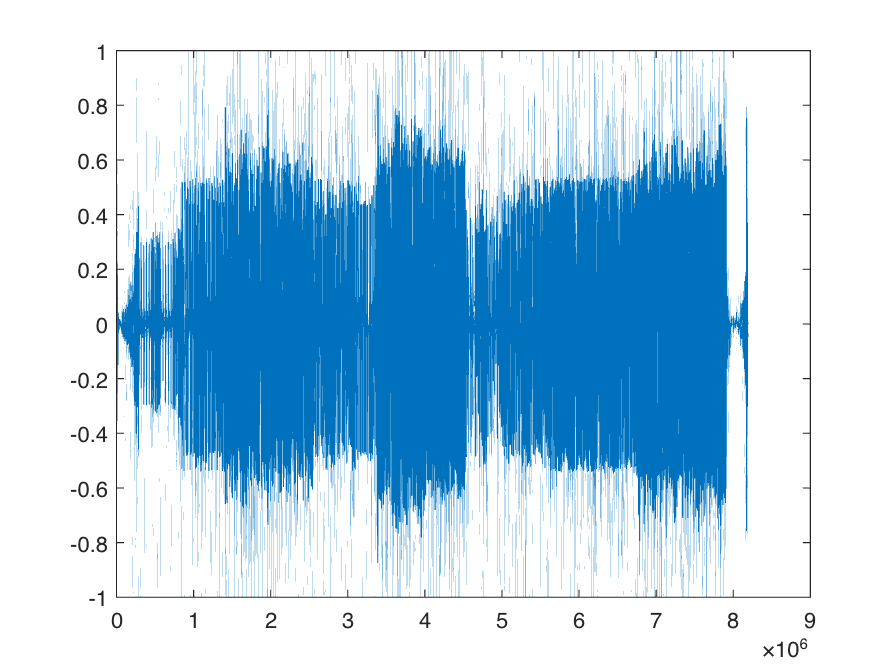


% data rate
rate = huffman(p);
H = entropyOfDistribution(p);


%I = y_quantize ; 
%y_quantize = zeros(1,8192000);
%y_quantize(1:1,1:6000000) = I;

% Inverse cosine transform
yhat = cellfun(@(row) idct(row*delta), y_quantize,'UniformOutput',false);

test = reshape(cell2mat(yhat),[],1);
plot(test)

plot(raw_audio)


%yhat = idct(y_quantize*delta);
diff = raw_audio_blocks - cell2mat(yhat);
% Distorsion
D = mean(mean(diff.^2));
%SNR
SNR = 10*log10(var(raw_audio)/D);

fprintf('Rate: %.4f dB',rate)

Rate: 4.3246 dB

fprintf('Entropy: %.4f dB',H)

Entropy: 4.2873 dB

fprintf('SNR: %.2f dB',SNR)

SNR: 33.08 dB





%AAodd = Aodd.*1/sqrt(2) + Aeven.*1/sqrt(2);
%AAeven = Aeven.*1/sqrt(2) - Aodd.*1/sqrt(2) ;

%plot(Aodd,Aeven,'.')
%plot(AAodd, AAeven, '.')


%xhat = q(1:10000)*delta;



%l = huffman(xhat);

function out = quantize(x, delta)

out = round(x/delta);

end
function index = uniqueIndex(x)

[~,~,index] = unique(x);

end